# MATLABでQiitaへ記事を投稿してみた

## はじめに

MATLABのスクリプトでQiitaへ記事を投稿したい衝動に駆られたので、いろいろと試行錯誤をしてみました。

## Qiita APIを調べる

 [Qiita APIのドキュメント](https://qiita.com/api/v2/docs) をみると、[POST /api/v2/items](https://qiita.com/api/v2/docs#post-apiv2items) というAPIを使うことで記事が投稿できそうです。

## アクセストークンの準備

RESTのGETメソッド以外はアクセストークンが必要だと[認証認可](https://qiita.com/api/v2/docs#%E8%AA%8D%E8%A8%BC%E8%AA%8D%E5%8F%AF)に書かれています。

今回はPOSTメソッドを使用するので、アクセストークンを発行しなければいけません。

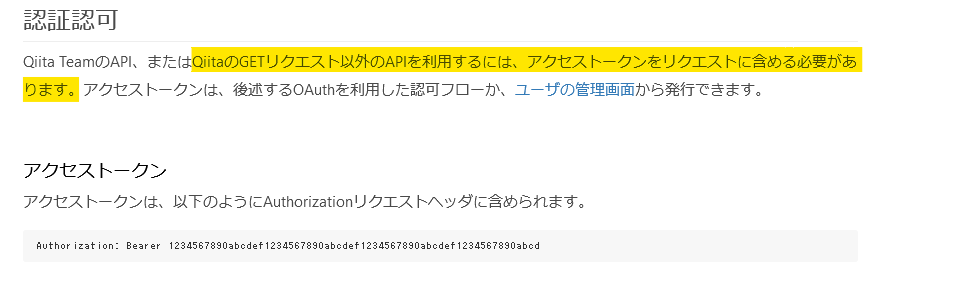

ちなみに、アクセストークンを使わずにGET以外のAPIを使用するとHTTP 401エラーが帰ってきます。

### 1. アクセストークンの発行

- [ユーザーの管理画面](https://qiita.com/settings/applications) へいき、**個人用アクセストークン**の**新しいトークンを発行する**をクリックします。 

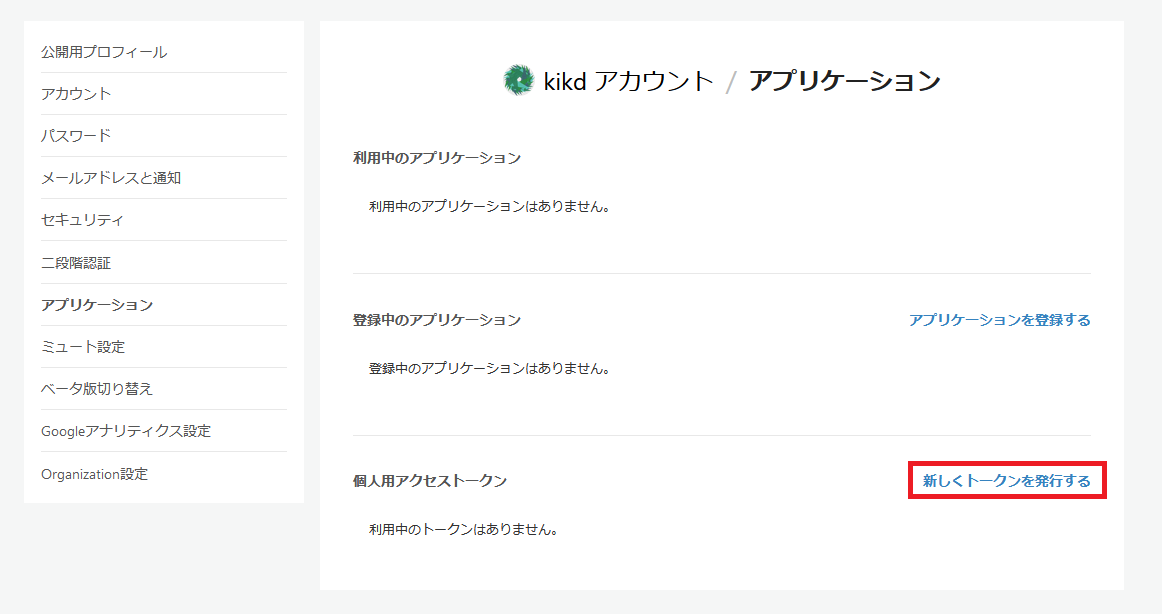

- アクセストークンの説明になにかしら入力し、 **write_qiita**にチェックをつけて**発行する**をクリックします。(説明は日本語でも大丈夫です)

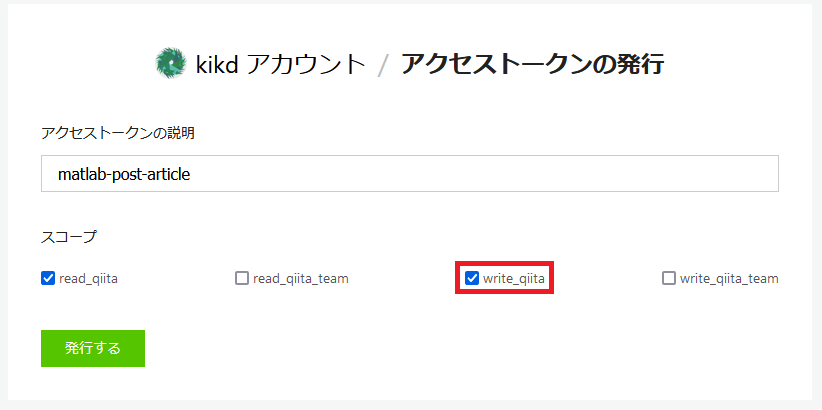

- アクセストークンが発行されているので、コピーしておきます。 (トークンは再表示されません！！)

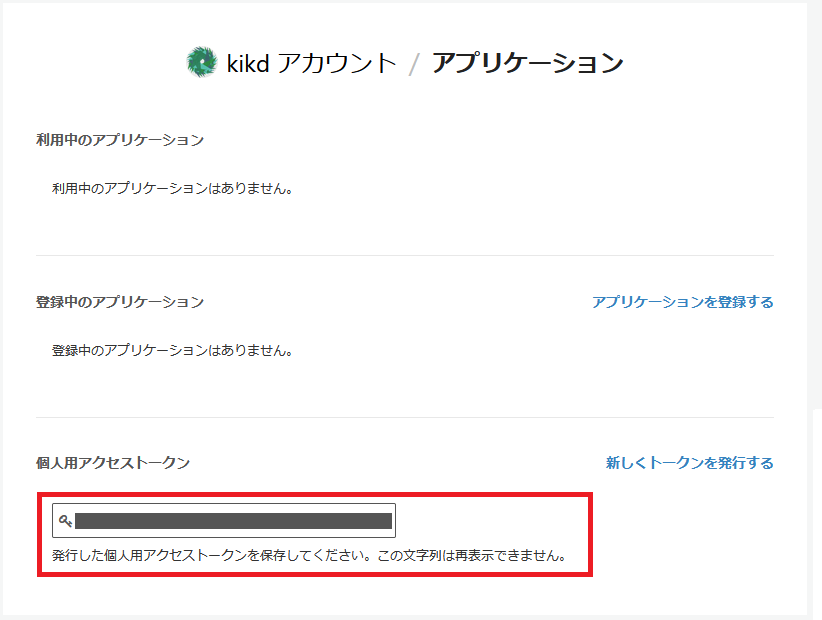

### 2. 発行されたトークンを環境設定する

言うまでもないですが、トークンは認証情報なので丁重に扱います。

環境変数に設定しておくと、ソースコードに直接書かずに済むのでオススメです。

getenv関数で任意の環境変数を取得でき、isemptyで設定有無を判定できます。

% 例：環境変数($QIITA_TOKEN)からトークンの情報を引っ張ってくる。値はてきとう
token=getenv('QIITA_TOKEN');
if (isempty(token))
    error("トークンが環境変数に設定されていません。");
else
    % リクエスト時のAuthorizationヘッダにフォーマット
    % 最後に使います！
    auth_header = strjoin({'Bearer' token}, ' ')
end

auth_header = 'Bearer 1234567890123456789012345678901234567890'

## APIを使って実際に投稿してみる

APIに必要なトークンの設定ができたので、APIを使ってみます。

タイトルを含んだLive Scriptであることを前提とし、実験では次のLive Scriptを使用しました。

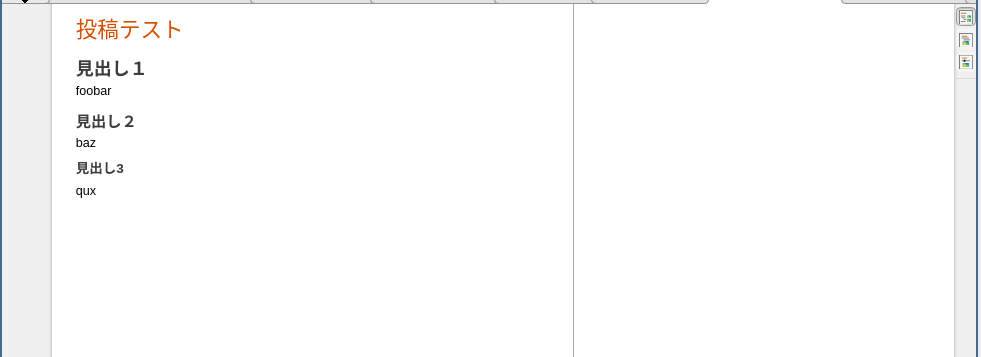

### 1.  APIに渡すデータづくり

#### 1-1 markdownからタイトルと本文を取得

タイトルと本文は@eigsさんが公開している[livescript2markdown](https://jp.mathworks.com/matlabcentral/fileexchange/73993-livescript2markdown-matlab-s-live-scripts-to-markdown)で生成されたmarkdownから取得します。

mdtext=fileread("なにか.md")

mdtext =     '# 投稿テスト
     # 見出し１
     
     
     foobar
     
     
     ## 見出し２
     
     
     baz
     
     
     ### 見出し3
     
     
     qux
     
     
     '


Live Script上の**タイトル**と**見出し1**がmarkdownでは同じ見出しレベルになっています。

タイトルは必ず1行目に来るため、1行目をタイトル、2行目以降を本文とします。

splited_text = split(mdtext, newline);
title = erase(splited_text{1}, regexpPattern("^# ")) % 行頭の# だけ消す

title = '投稿テスト'

text = strjoin(splited_text(2:end),newline)

text =     '# 見出し１
     
     
     foobar
     
     
     ## 見出し２
     
     
     baz
     
     
     ### 見出し3
     
     
     qux
     
     
     '


これで、タイトルと本文の作成ができました。

#### 1-2 タグの作成

タグは最大5つ指定できます。

6つ以上指定した場合はリクエストを投げてもエラーが帰ってくるので、事前に弾いてしまいます。

ドキュメントのexampleには**versionsプロパティ**がついていますが、つけなくても問題ありません。

以下のコードでタグのデータを作成できます。

tags = ["matlab" "QiitaAPI" "RestAPI"];
tag_count = length(tags);
if(tag_count > 5)
    error("タグが多すぎます");
end
article_tag = {tag_count};
for i = 1:tag_count
    article_tag{i} = struct('name', tags{i});
    display(article_tag{i})
end

  フィールドをもつ struct:

    name: 'matlab'

  フィールドをもつ struct:

    name: 'QiitaAPI'

  フィールドをもつ struct:

    name: 'RestAPI'



#### 1-3 リクエストデータの作成

1-1でタイトルと本文を、1-2でタグを作成しました。

これらのデータを結合して、リクエストデータを作成します。

コードでは、Qiita Teamsのみ有効な**coeditingプロパngティ**、**group_url_nameプロパティ**は無視しています。

article_body = struct("body",text, "private", true, ...
    "tags", {article_tag}, "title",title, "tweet", false);
jsonencode(article_body, 'PrettyPrint',true)

ans =     '{
       "body": "# 見出し１\n\n\nfoobar\n\n\n## 見出し２\n\n\nbaz\n\n\n### 見出し3\n\n\nqux\n\n\n",
       "private": true,
       "tags": [
         {
           "name": "matlab"
         },
         {
           "name": "QiitaAPI"
         },
         {
           "name": "RestAPI"
         }
       ],
       "title": "投稿テスト",
       "tweet": false
     }'


### 2. リクエストの送信

APIに渡すデータが作成できたので、実際にリクエストを送信します。

webwrite関数を使うことで、POSTリクエストを送信できます。

%% APIの指定とヘッダの設定

% POST /api/v2/items
uri = 'https://qiita.com/api/v2/items';

% 最初の方で取得したトークンをAuthorizationヘッダにつける
webopt = weboptions(...
    'ContentType', 'json',...
    'HeaderFields', {
        'Origin' 'https://qiita.com'
        'Authorization' auth_header
    }...
);

try
  response = webwrite(uri, article_body, webopt);
  result = response.url;
catch ME
  result = ME.identifier;
end

リクエストに成功した場合、**result**には記事のURLが渡されます。

リクエストに失敗した場合、**result**にはエラーの内容が渡されます。

## 注意事項とか

残念ながら、REST API越しでは画像のアップロードまではできませんでした。

画像を含んだLive Scriptを投稿する場合は一度限定公開にして投稿し、手作業で画像をアップロードする必要があります。

## まとめとか

MATLAB上でQiitaの記事を投稿する方法を調べてまとめてみました。

...ということで、この記事もAPI経由で作成し、手作業で画像をアップロードして公開しています。